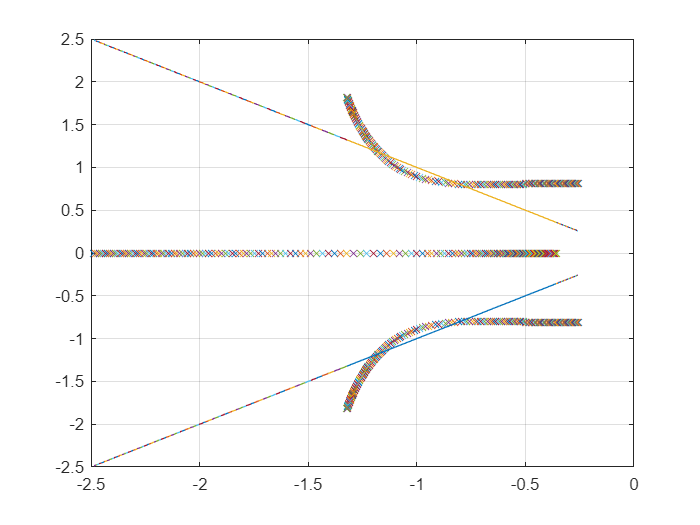

clear;
K = 0:0.01:2;
n = length(K);
for i = 1:n
    num1 = [K(i) 0.9]; den1 = [1 0]; sys1 = tf(num1, den1);
    num2 = [1]; den2 = [0.5 1.5 1]; sys2 = tf(num2, den2);
    sys = sys1 * sys2;
    sys_cl = feedback(sys, 1);
    p(:, i) = pole(sys_cl);
end
plot(real(p), imag(p), 'x', real(p), -real(p), real(p), real(p)), grid


t = 0:0.001:7;
K = 0.8:0.01:1.2;
n = length(K);
t_p = 100.0;
K_t_p = 0.0;
i_t_p = 0.0;
y_max = 0.0;
t_s = 0.0;
for i = 1:n
    num1 = [K(i) 0.9]; den1 = [1 0]; sys1 = tf(num1, den1);
    num2 = [1]; den2 = [0.5 1.5 1]; sys2 = tf(num2, den2);
    sys = sys1 * sys2;
    sys_cl = feedback(sys, 1);
    [y, ~] = step(sys_cl, t);
    [max_y, max_y_index] = max(y);
    if max_y > 1
        if t(max_y_index) < t_p
            t_p = t(max_y_index);
            i_t_p = i;
            K_t_p = K(i);
            y_max = max_y;
        end
    end
end
K_t_p

K_t_p = 1.0700

t_p

t_p = 3.3370

y_max

y_max = 1.0012


num1 = [0.82 0.9]; den1 = [1 0]; sys1 = tf(num1, den1);
num2 = [1]; den2 = [0.5 1.5 1]; sys2 = tf(num2, den2);
sys = sys1 * sys2;
sys_cl = feedback(sys, 1);
% pzmap(sys_cl)
[y1, ~] = step(sys_cl, t);

num1 = [1.07 0.9]; den1 = [1 0]; sys1 = tf(num1, den1);
num2 = [1]; den2 = [0.5 1.5 1]; sys2 = tf(num2, den2);
sys = sys1 * sys2;
sys_cl = feedback(sys, 1);
% pzmap(sys_cl)
[y2, ~] = step(sys_cl, t);

[max_y1, max_y1_index] = max(y1);
y1_t = t(max_y1_index);

[max_y2, max_y2_index] = max(y2);
y2_t = t(max_y2_index);

n = length(t)

n = 7001

for i = 1:n
    if y2(i) > 1 - 0.02
        t_s = t(i)
        break
    end
end

t_s = 2.5640

t_s

t_s = 2.5640

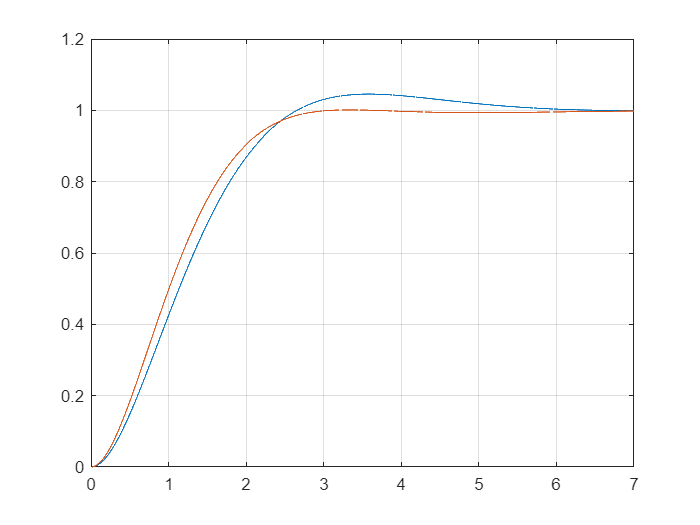

plot(t, y1, t, y2), grid

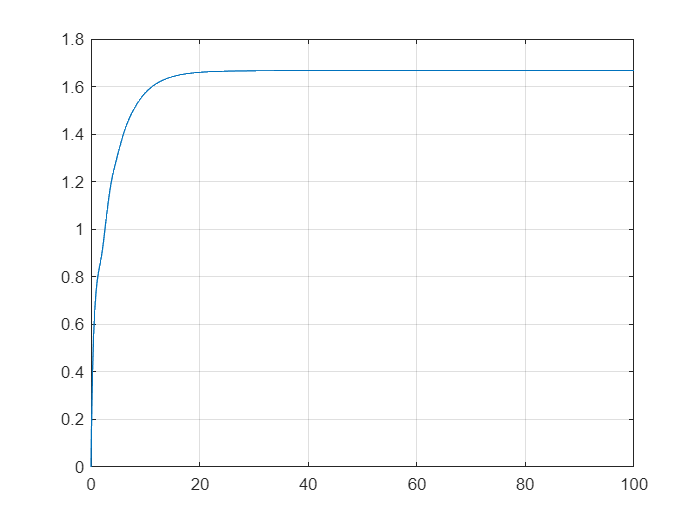

clear;
K = 1;
num1 = K * [1 1]; den1 = [1]; sys1 = tf(num1, den1);
num2 = [2]; den2 = [1 4 0]; sys2 = tf(num2, den2);
num3 = [3]; den3 = [1 2 5]; sys3 = tf(num3, den3);
sys = sys1 * sys2;
sys_cl = feedback(sys, sys3);

t = 0:0.1:100;
[y, ~] = step(sys_cl, t);
plot(t, y), grid;